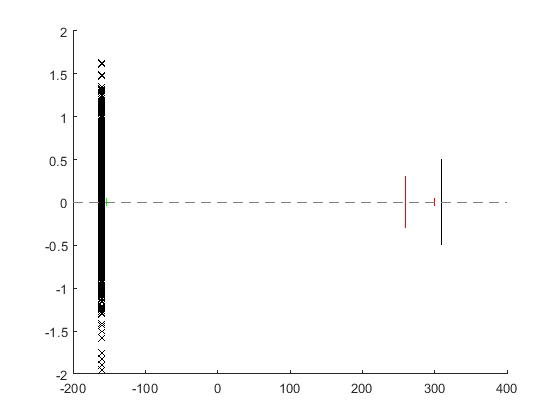

addpath("functionsAndGUI\")
tic
%clear all;

%plot setup with
beamon=false;

%Goebel specification 
NRays=1E3; %number of rays per source
Ngoebel=1E3; %Number of sources on Goebel mirror

delta=0.03; %divergence angle
fwhm=1.35; %fwhm of Goebel source distr.
ds=160; %distance to sources on sarm
dgoebelsslit=7; %distance Goebel to source slit
gammas=90; %Goebel mirror rotation [deg] (90=not rotated)



%slit specifications
wsslit=0.1; %width source slit
wantisc=0.6; %width anti-scatter slit
wdslit=0.1; %width detector slit
dantisc=260; %distance antiscatter slit on darm
ddslit=300; %distance detector slit on darm

%sample specifications
wsample=10;
offset=0;
gammasample=0;
h=0;

%detector speficications
dd=310;
wd=1;
NPixels=100;

%Rocking Curve specifications
tt=0; %2theta
alpha_min=tt/2-0.04;
alpha_max=tt/2+0.04;
incr=0.001;




%items calculations
gammasslit=90; gammadslit=90; gammaantisc=90; gammad=90;
dsslit=ds-dgoebelsslit;

%Create setup
setup=startsetup();

setup=add_goebel(setup,ds,gammas,fwhm,Ngoebel,NRays,delta);
setup=add_sslit(setup,dsslit,wsslit, gammasslit);
setup=add_sample(setup,wsample,offset,gammasample);
setup=add_dslit(setup,dantisc,wantisc,gammaantisc);
setup=add_dslit(setup,ddslit,wdslit,gammadslit);
setup=add_detector(setup,dd,wd, gammad,NPixels);


%plot basic, non-rotated setup with beams off or on depending on beamon
fig1=plot_setup(setup,0,0,beamon,dd+1);



%Rocking Curve 
[alpha,J]=Scan_Rocking(setup,tt,h,alpha_min,alpha_max,incr);

ans = -0.0400

ans = -0.0390

ans = -0.0380

ans = -0.0370

ans = -0.0360

ans = -0.0350

ans = -0.0340

ans = -0.0330

ans = -0.0320

ans = -0.0310

ans = -0.0300

ans = -0.0290

ans = -0.0280

ans = -0.0270

ans = -0.0260

ans = -0.0250

ans = -0.0240

ans = -0.0230

ans = -0.0220

ans = -0.0210

ans = -0.0200

ans = -0.0190

ans = -0.0180

ans = -0.0170

ans = -0.0160

ans = -0.0150

ans = -0.0140

ans = -0.0130

ans = -0.0120

ans = -0.0110

ans = -0.0100

ans = -0.0090

ans = -0.0080

ans = -0.0070

ans = -0.0060

ans = -0.0050

ans = -0.0040

ans = -0.0030

ans = -0.0020

ans = -0.0010

ans = 0

ans = 0.0010

ans = 0.0020

ans = 0.0030

ans = 0.0040

ans = 0.0050

ans = 0.0060

ans = 0.0070

ans = 0.0080

ans = 0.0090

ans = 0.0100

ans = 0.0110

ans = 0.0120

ans = 0.0130

ans = 0.0140

ans = 0.0150

ans = 0.0160

ans = 0.0170

ans = 0.0180

ans = 0.0190

ans = 0.0200

ans = 0.0210

ans = 0.0220

ans = 0.0230

ans = 0.0240

ans = 0.0250

ans = 0.0260

ans = 0.0270

ans = 0.0280

ans = 0.0290

ans = 0.0300

ans = 0.0310

ans = 0.0320

ans = 0.0330

ans = 0.0340

ans = 0.0350

ans = 0.0360

ans = 0.0370

ans = 0.0380

ans = 0.0390

ans = 0.0400

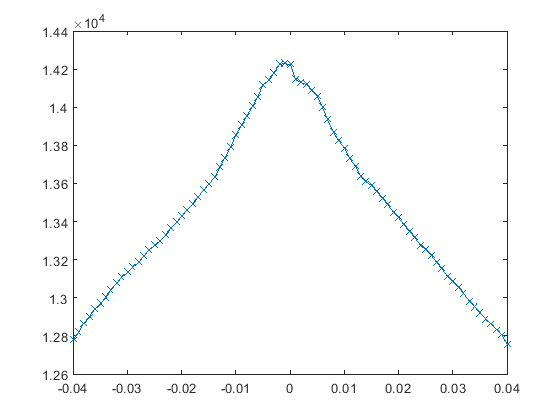

figure
plot(alpha,J,'x-');

toc

Elapsed time is 6.913389 seconds.
